# SPEECH PROCESSING LAB-3

180020002

## AIM

- To identify optimal sampling frequency for speech signal processing.

- To identify optimal bit resolution for speech signal processing.

- To understand significance of telephone bandwidth.

- To understand the difference between narrowband and wideband speech.

## **THEORY**

**INTRODUCTION**

Speech signal processing on a digital machine needs sampling and storing of the analog version of the speech signal generated at the output of microphone. Sampling frequency is the parameter that controls the sampling process. The number of bits per sample is the parameter that controls the bit resolution. The intelligibility, amount of information and also the perceptual quality of speech depends on these two parameters. The experimental analysis to learn the significance of these two parameters is the aim of this experiment.

#### SAMPLING THEOREM AND SAMPLING FREQUENCY

The sampling of analog signal is based on sampling theorem. The sampling theorem states that if fm is the maximum frequency component in the analog signal, then the information present in the signal can be represented by its sampled version provided the number of samples taken per second is greater than or equal to twice the maximum frequency component. The number of samples/second is more commonly termed as sampling frequency fs. According to sampling theorem, fs should be greater than or equal to 2 fm.

The speech signal has frequency components in the audio frequency range (20 Hz to 20 kHz) of the electromagnetic spectrum. This is the reason for perceiving the information present in the speech signal by human ears. The fundamental question is upto what range of audio frequency, the speech signal has frequency components. We can analyze this experimentally by considering the whole audio range. The standard sampling frequency to sample the entire audio range is 44.1 kHz. This is because, 20 kHz is the maximum frequency component and allowing some guard band, the sampling frequency has been set at 44.1 kHz. There are no significant frequency components in the spectrum beyond about 7.5 kHz. This observation shows that 44.1 kHz sampling is too high value to capture the information present in the speech signal. Most of the speech signal has frequency components only upto 8 kHz. Thus 16 kHz seems to be optimal sampling frequency for the case of speech.

#### TELEPHONE BANDWIDTH SPEECH

The speech signal has frequency components upto 8 kHz and hence 16 kHz is the optimal sampling frequency. However, when telephone communication started, with bandwidth being a precious resource, the speech signal was passed through an anti-aliasing low pass filter with cutoff frequency of 3.3 kHz and sampled at 8 kHz sampling frequency. Thus the speech signal collected over telephone networks will have a message bandwidth of about 4 kHz.

Information beyond 4 kHz is eliminated in case of telephone bandwidth speech. Even though the sampling frequency seems to be fine for sounds like *a* and *aa*, it severely affects other sounds like *s* and *sh*. However, information upto 4 kHz bandwidth seem to be sufficient for intelligible speech. If the sampling frequency is further decreased from 8 kHz, then intelligibility of speech degrades significantly. Hence 8 kHz was chosen as the sampling frequency for the telephone communication. By listening to the three files, namely, file sampled at 44.1 kHz, file sampled at 16 kHz and file sampled at 8 kHz, one can observe difference in the naturalness between the speech sampled at 8 kHz and other higher sampling frequencies. Thus wherever possible, the speech signal sampled 16 kHz should be used for signal processing.

#### NARROWBAND VS WIDEBAND SPEECH

The speech signal sampled at 8 kHz is termed as narrowband speech and the speech signal sampled at 16 kHz is termed as wideband speech. For practical speech signal processing, if the speech signal is available from a telephone or mobile channel, we have left with little option, but to process the speech signal at 8 kHz sampling frequency. Recently, methods are being developed to convert narrowband speech to wideband speech. Alternatively, if the speech signal is available from a wideband channel, then 16 kHz sampling frequency is suggested. The final proposal is 16 kHz is the optimal sampling frequency for speech. Rest of the study about bit resolution is therefore performed using wideband speech.

#### BIT RESOLUTION FOR SPEECH

After the sampling frequency, the next important parameter in the digitization process of speech is bit resolution. The number of bits used for storing each sample of speech is termed as bit resolution. The number of bits/sample in turn depends on the number of quantization levels used during analog to digital conversion. More the number of quantization levels, finer will be the quantization step and hence better will be the information preserved in the digitized form. However, more will be the requirement of number of bits/sample. Hence it is a trade off between the number of bits and information representation. The effect of bit resolution can be analyzed experimentally. For this experiment the optimal sampling frequency of 16 kHz can be used as proposed earlier.

All speech signal processing applications invariably use 16 bits/sample as bit resolution. The number of quantization levels will therefore be 2^16=65536 and are found to be optimal for preserving information present in the analog version of the speech signal. The next lower bit length possible with binary power is 8 bits. With 8 bits, the number of quantization levels will be 2^8=256. As it can be observed, the number of quantization levels are significantly lower compared to the 16 bit case and hence poor representation of information in the quantized signal. 

The waveforms and magnitude spectra for 16 bit and 8 bit cases seem to be similar visually. Thus there may not be significant decrease in the information content represented by 16 bit and 8 bit cases. However, by digitization we know that there is significant decrease in the number of quantization levels. By listening to the speech signals one can make out decrease in perceptual quality, especially, perception of some quantization noise. The next lower bit resolution possible in terms of binary power is 2^4=16. That is, the binary word will have length of 4 bits and there will be 16 different quantization levels.

both the waveform and spectra are significantly distorted compared to the 16 bit versions. Perceptually also their will be lot of quantization noise. Thus this shows that 4 bit is not recommended as bit resolution for the case of speech. The lowest possible bit resolution in terms of binary power is 2^1=2. The binary word will have 1 bit length and there are two quantization levels. 

By visual perception we may conclude that there may not be any information left in the speech signal with 1 bit resolution. **An interesting observation will be to listen to the speech signal with 1 bit resolution. Perceptually we can still make out the information present in the speech signal, ofcourse with lot of quantization noise. This makes us to understand one important point about speech, that is, information lies in the sequence, not only by the amplitude value of the samples.**

All these studies indicate that, 16 bit is best preferable bit resolution and 1 bit is the worst case. Definitely 4 bit resolution is not preferable. The choice is between 8 and 16 bits. Even though by visual inspection both signals look similar, listening to the signals do infer that the quantization level is audible in case of 8 bits. Therefore wherever possible, 16 bit resolution is preferable. Hence 16 bit resolution is proposed as the optimal bit resolution. Finally it is be mentioned at this point that all these discussion is with respect to uniform quantization. There are several alternative coding techniques which need bit resolution far less than 16 bits. They will be studied as part of speech coding. At the first level this information is sufficient to appreciate the significance of bit resolution.

#### BITRATE FOR SPEECH COMMUNICATION

Bit rate is defined as sampling frequency multiplied by bit resolution. For land line telephone, the sampling frequency followed is 8 kHz and bit resolution is 8 bits and hence the bit rate is 64 kbps. For mobile communication, even though the sampling frequency remains same at 8 kHz, the bit resolution varies over a wide range starting from 8 bits/sample to 0.25 bits/sample and accordingly we have wide bit rate ranging from 64 kbps to as low as 2 kbps. Alternatively, in case of wideband speech like television broadcasting, the bit rate may be as high as about 256 kbps.

## SPEECH SIGNAL ANALYSIS AND PLOTS

A. Study of Sampling Frequency 

a. Record the word ‘Speech’ using a sampling frequency of 44.1kHz save it in a .wav file. Plot the complete speech signal and the frequency spectrum for different sounds. 

b. Resample the above speech signal to 16kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 16kHz as compared to the speech signal sampled at 44.1kHz and whether this is a good choice for the sampling frequency. 

c. Resample the speech signal obtained from (a) to 8kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 8kHz comparing it to the above signals and whether this is a good choice for the sampling frequency.

 d. Resample the speech signal obtained from (a) to 4kHz and plot the complete speech signal along with the frequency spectra for different sounds. Comment on the intelligibility of the speech signal sampled at 4kHz comparing it to the above signals and whether this is a good choice for the sampling frequency. 

Analysis @44100Hz


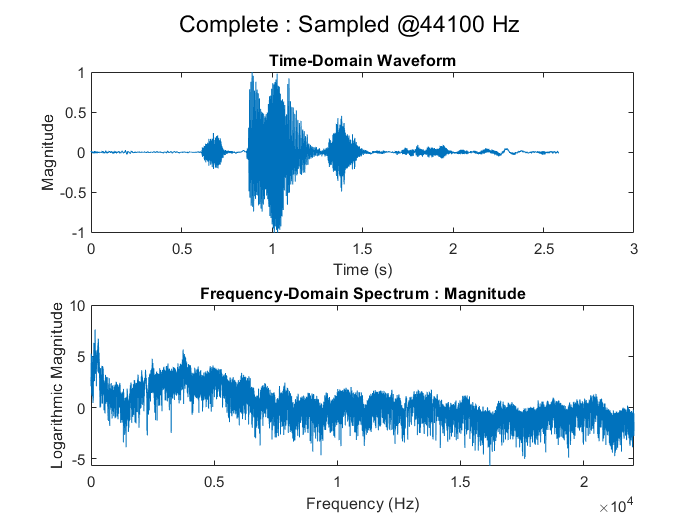

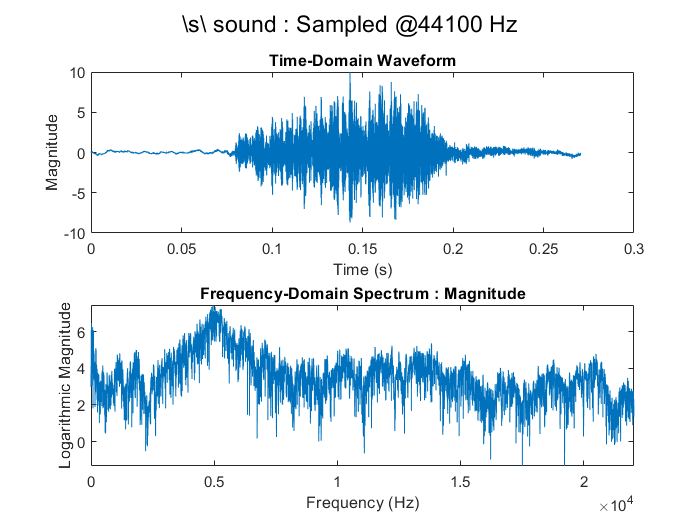

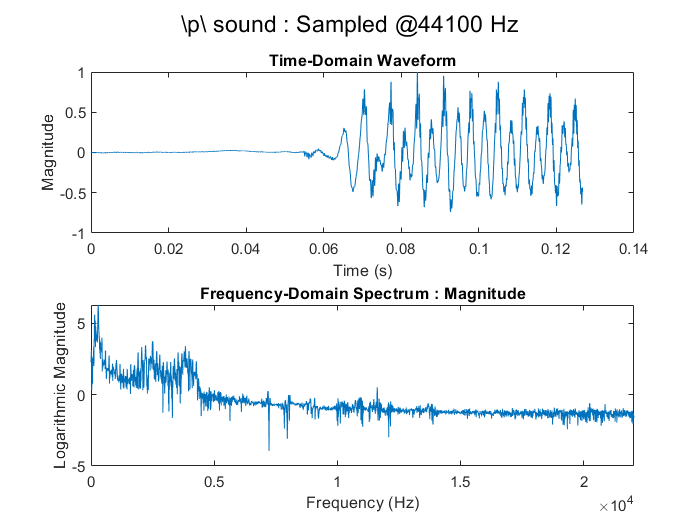

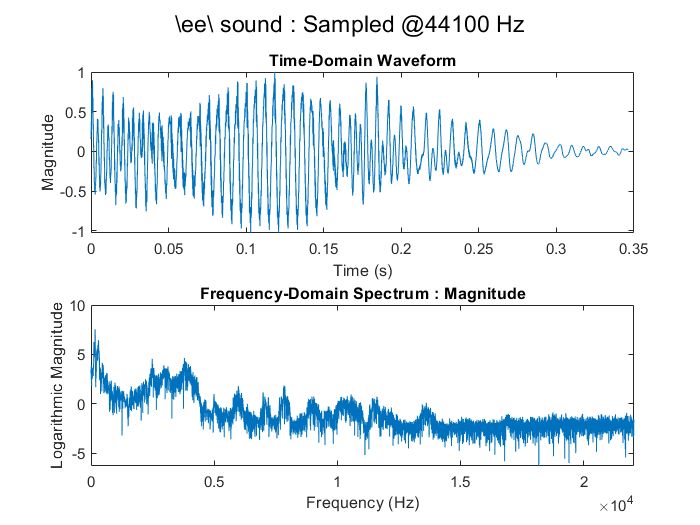

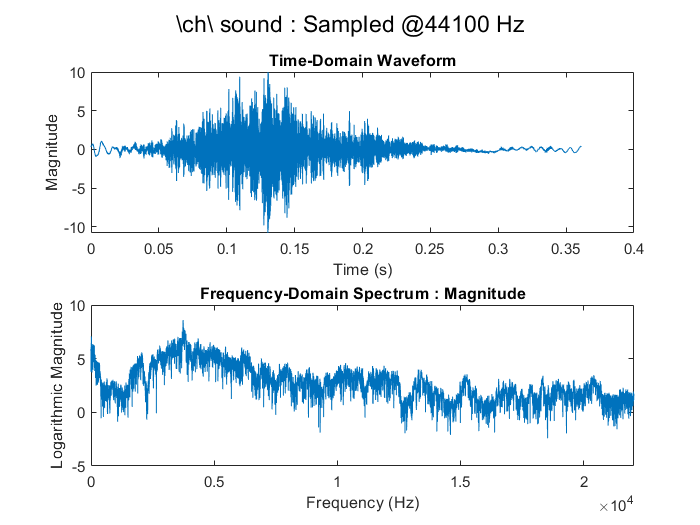

Analysis @16000Hz


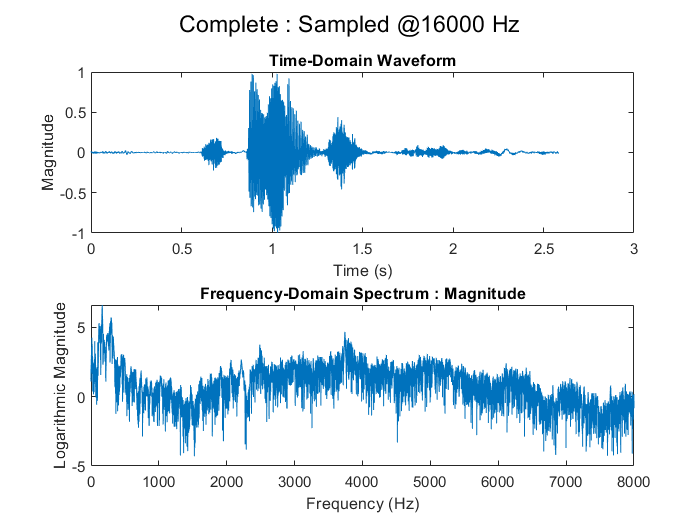

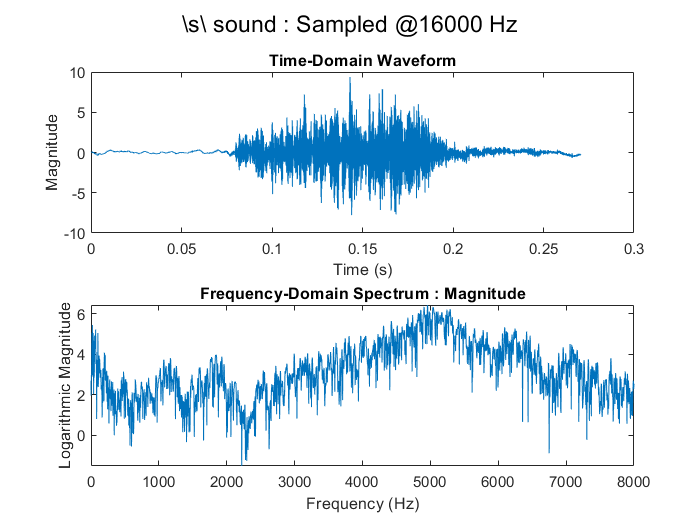

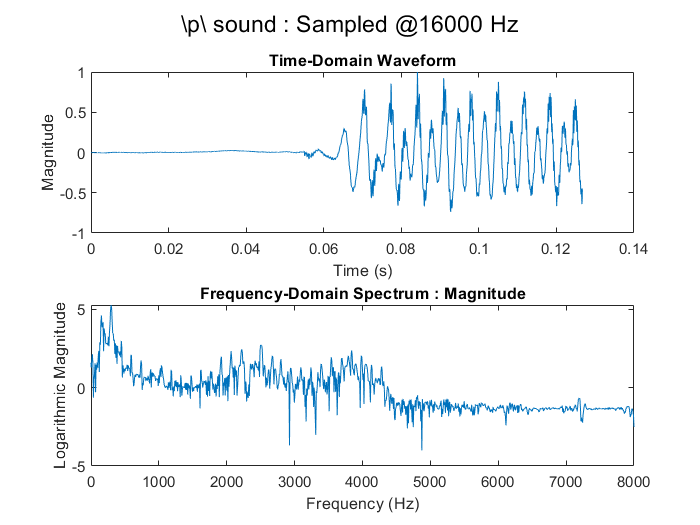

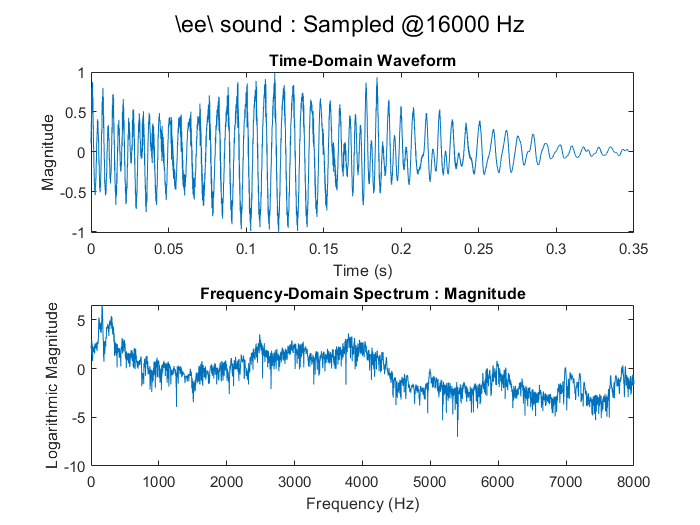

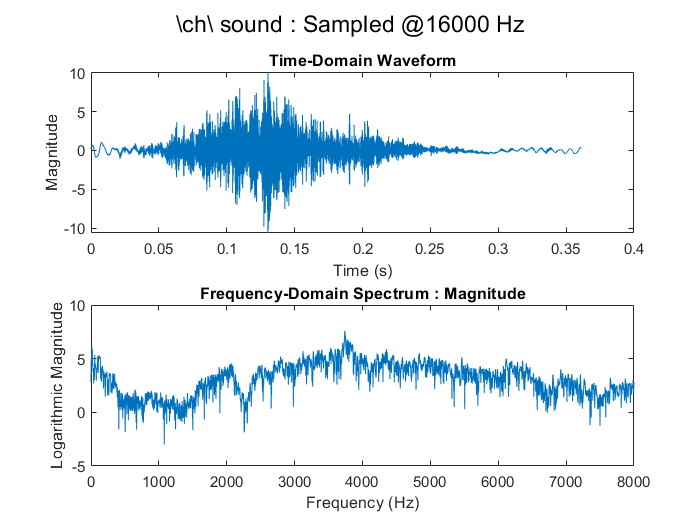

Analysis @8000Hz


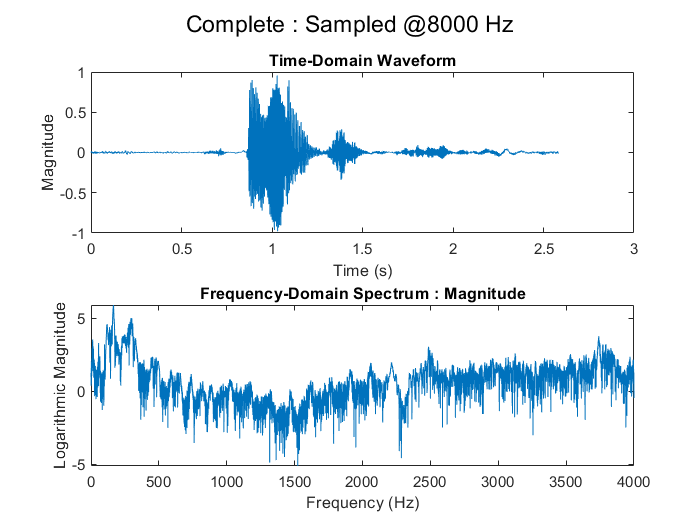

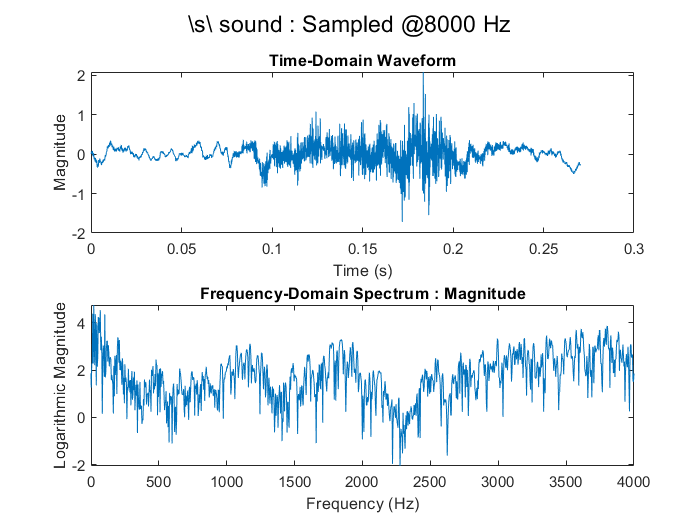

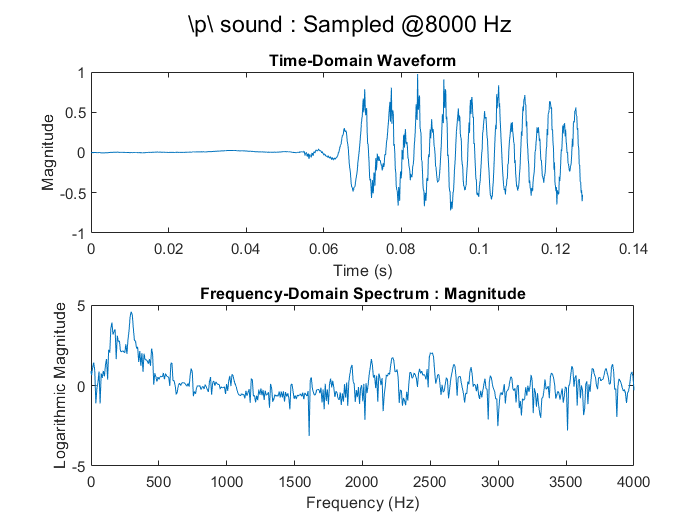

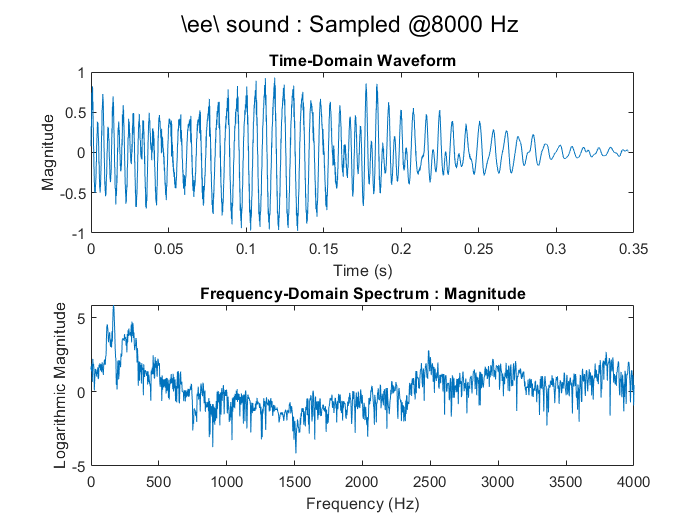

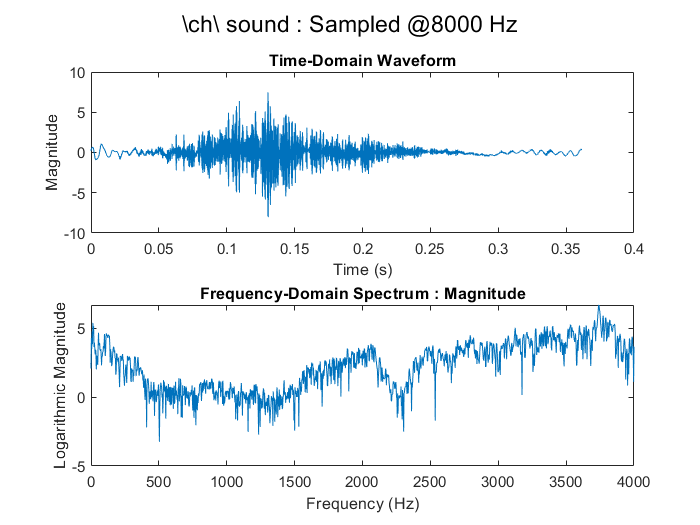

Analysis @4000Hz


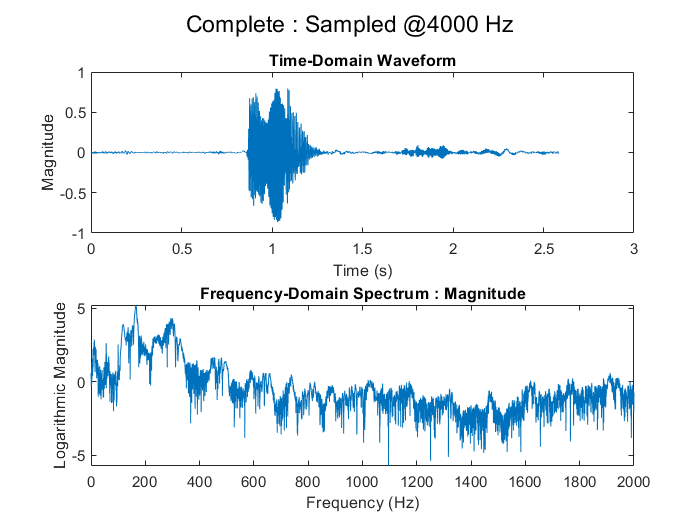

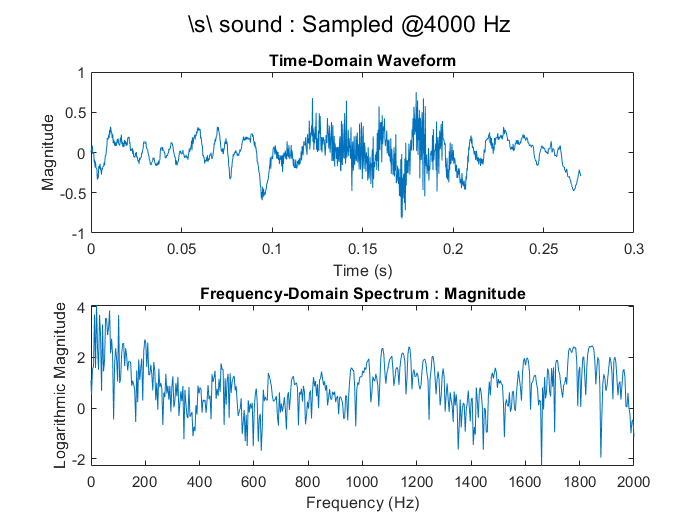

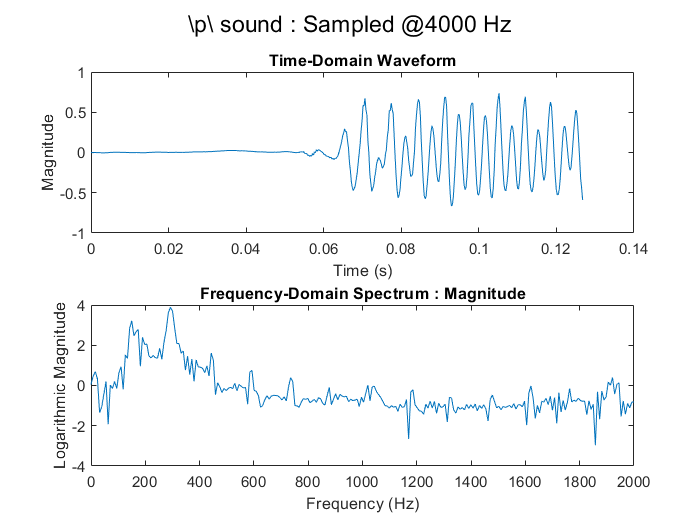

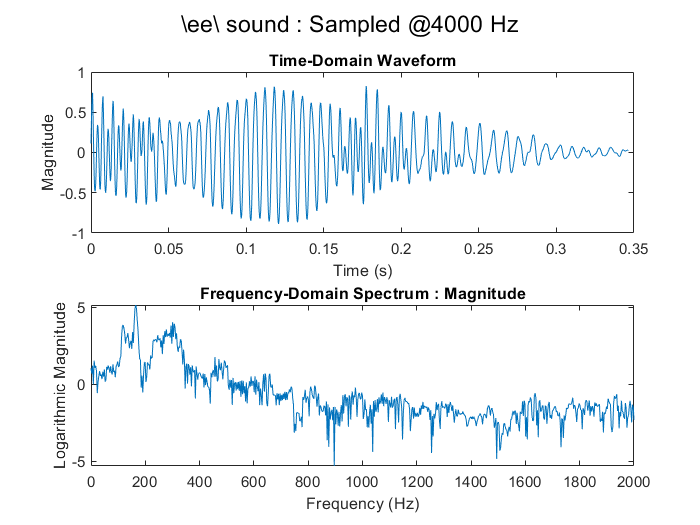

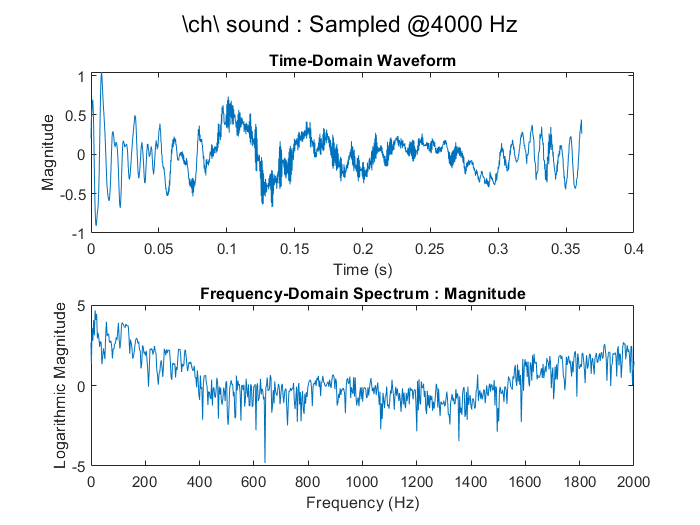

warning('off','all')
%Loading sounds
[overallSpeech, Fs] = audioread('Recordings\\Word_speech.wav');
[s_soundSpeech, Fs] = audioread('Recordings\\Word_speech_sound_s.wav');
[p_soundSpeech, Fs] = audioread('Recordings\\Word_speech_sound_p.wav');
[ee_soundSpeech, Fs] = audioread('Recordings\\Word_speech_sound_ee.wav');
[ch_soundSpeech, Fs] = audioread('Recordings\\Word_speech_sound_ch.wav');

soundList = {'Complete', '\s\ sound', '\p\ sound', '\ee\ sound', '\ch\ sound'};

sound44_1kHzArrays = {overallSpeech/max(overallSpeech), 10*s_soundSpeech/max(s_soundSpeech), p_soundSpeech/max(p_soundSpeech), ee_soundSpeech/max(ee_soundSpeech), 10*ch_soundSpeech/max(ch_soundSpeech)};
%Slight amplification was needed for some sounds

%Changing Sampling Rates
Fs_List = [44100, 16000, 8000, 4000];

sound16kHzArrays = {};
for index = 1:5
    sound16kHzArrays{end + 1} = resample(sound44_1kHzArrays{index}, Fs_List(2), Fs);
end

sound8kHzArrays = {};
for index = 1:5
    sound8kHzArrays{end + 1} = resample(sound44_1kHzArrays{index}, Fs_List(3), Fs);
end

sound4kHzArrays ={};
for index = 1:5
    sound4kHzArrays{end + 1} = resample(sound44_1kHzArrays{index}, Fs_List(4), Fs);
end

%Storing All Sounds in this Matrix
soundMatrix = {sound44_1kHzArrays, sound16kHzArrays, sound8kHzArrays, sound4kHzArrays};

%16kHz Analysis for all sounds

for i = 1:4
    Fs_Val = Fs_List(i);
    disp(strcat('Analysis @',string(Fs_Val), 'Hz'));
    soundArrays = soundMatrix{i};
    
    for j = 1:5
        
        soundArray = soundArrays{j};
        arrLen = length(soundArray);
        timeVector = linspace(0, arrLen, arrLen)/Fs_Val;
        
        soundArrayFFT = fftshift(fft(soundArray));
        freqVector = linspace(-Fs_Val/2, Fs_Val/2, arrLen);
        
        figure();
        sgtitle(strcat(string(soundList{j}) , ' : Sampled @', string(Fs_Val), ' Hz'));
        subplot(2, 1, 1);
        plot(timeVector, soundArray);
        title('Time-Domain Waveform');
        xlabel('Time (s)');
        ylabel('Magnitude');
        
        subplot(2, 1, 2);
        plot(freqVector, log(abs(soundArrayFFT)));
        title('Frequency-Domain Spectrum : Magnitude');
        xlabel('Frequency (Hz)');
        ylabel('Logarithmic Magnitude');
        xlim([0, Fs_Val/2]);
        
    end
    
end

**Observations **: As we decrease the sampling frequency, the lesser information about frequency is retained and we observed telephonic bandwidth and its limitations.

B. Study of Bit Resolution 

a. For this study, record the word ‘Speech’ using a sampling frequency of 16kHz and a bit resolution of 16 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds using the bit resolution of 16 bits/sample. 

b. Now, using the same speech signal sampled at 16kHz, now use a bit resolution of 8 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signal obtained using 16 bits/sample. 

c. Using the same speech signal sampled at 16kHz, now use a bit resolution of 4 bits/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signals. 

d. Using the same speech signal sampled at 16kHz, now use a bit resolution of 1 bit/sample. Plot the complete speech signal and the frequency spectrum of different sounds. Comment on the frequency spectrum of the different sounds, intelligibility and quality of the speech signal comparing it with the above speech signals. 

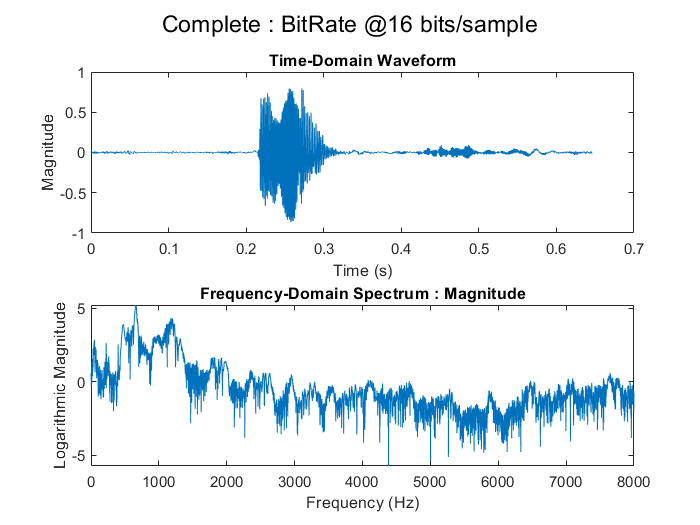

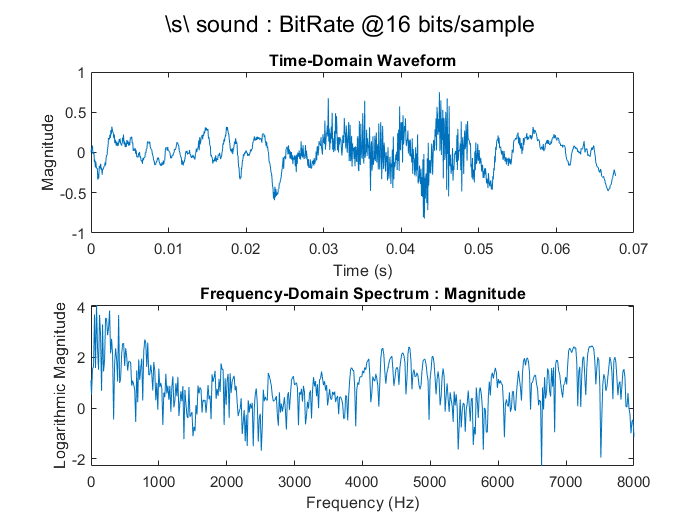

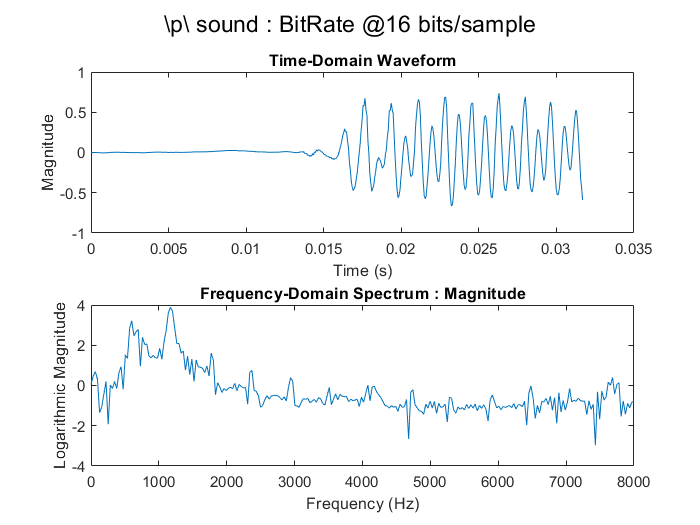

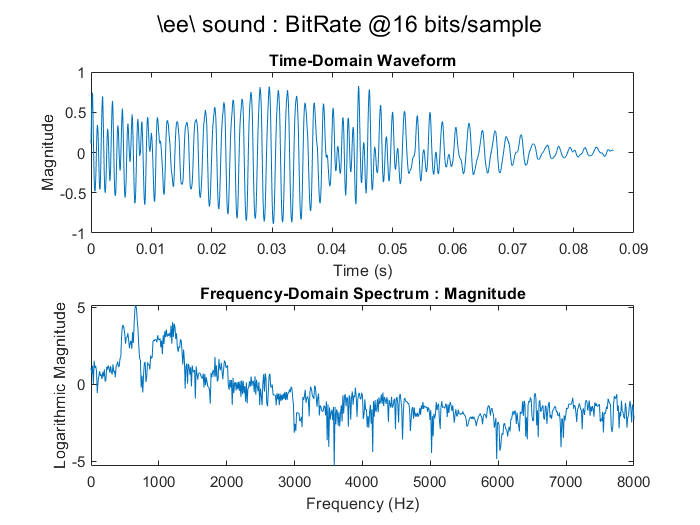

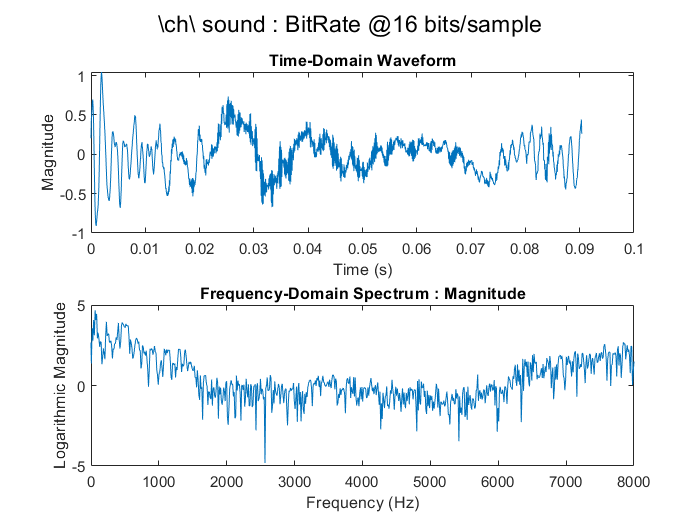

%Taking signals @ 16kHz
bitResolutionList = [16, 8, 4, 1];
quantLevels = [2^16-1, 2^8-1, 2^4-1, 2^1 - 1];

Fs_Val = 16000;
for j = 1:5
    
    soundArray = soundArrays{j};
    arrLen = length(soundArray);
    timeVector = linspace(0, arrLen, arrLen)/Fs_Val;
    
    soundArrayFFT = fftshift(fft(soundArray));
    freqVector = linspace(-Fs_Val/2, Fs_Val/2, arrLen);
    
    figure();
    sgtitle(strcat(string(soundList{j}), ' : BitRate @', '16', ' bits/sample'));
    subplot(2, 1, 1);
    plot(timeVector, soundArray);
    title('Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Magnitude');
    
    subplot(2, 1, 2);
    plot(freqVector, log(abs(soundArrayFFT)));
    title('Frequency-Domain Spectrum : Magnitude');
    xlabel('Frequency (Hz)');
    ylabel('Logarithmic Magnitude');
    xlim([0, Fs_Val/2]);
    
end

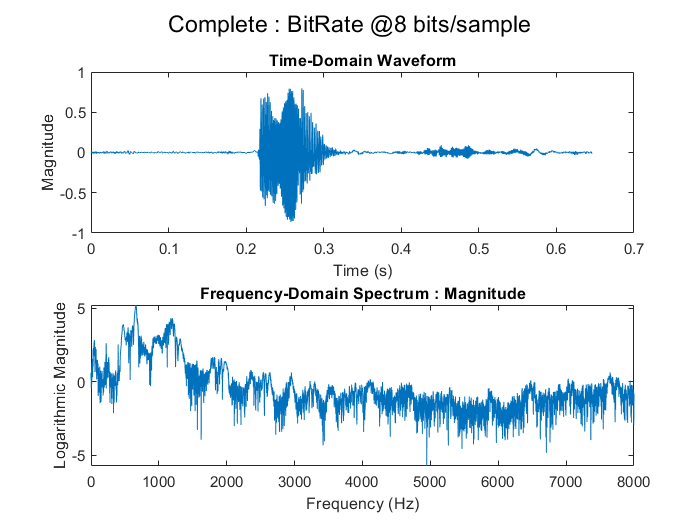

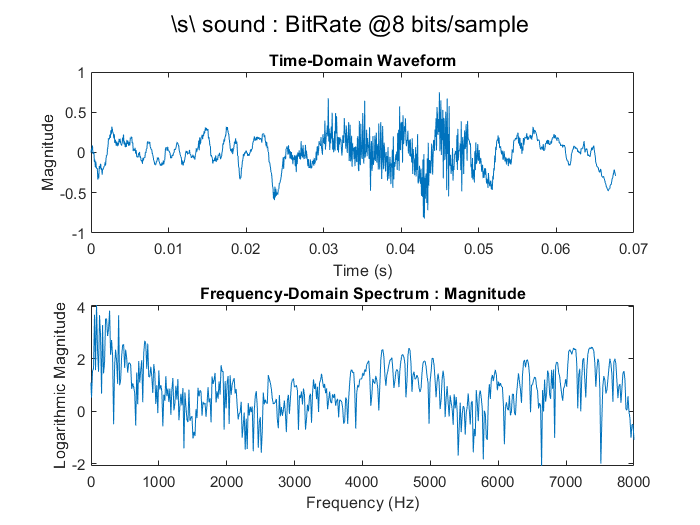

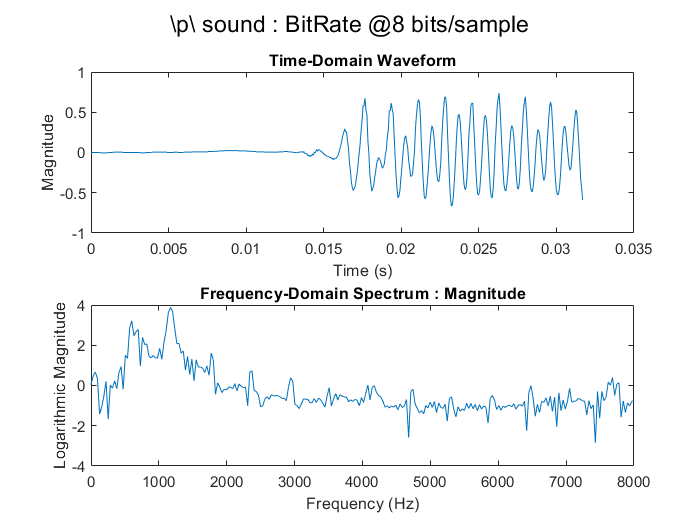

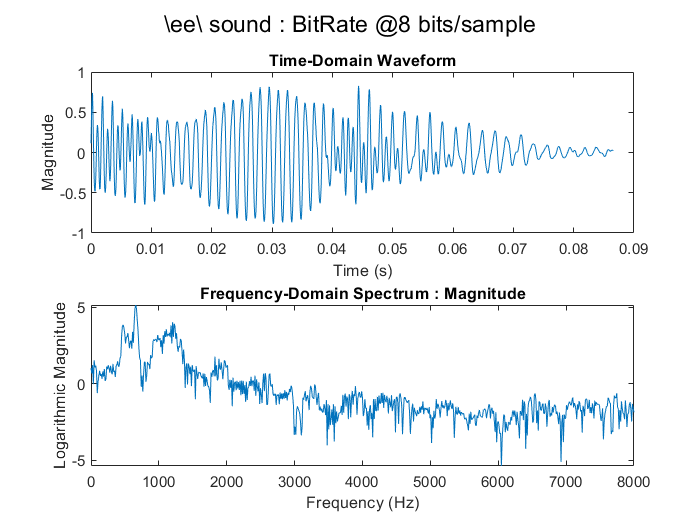

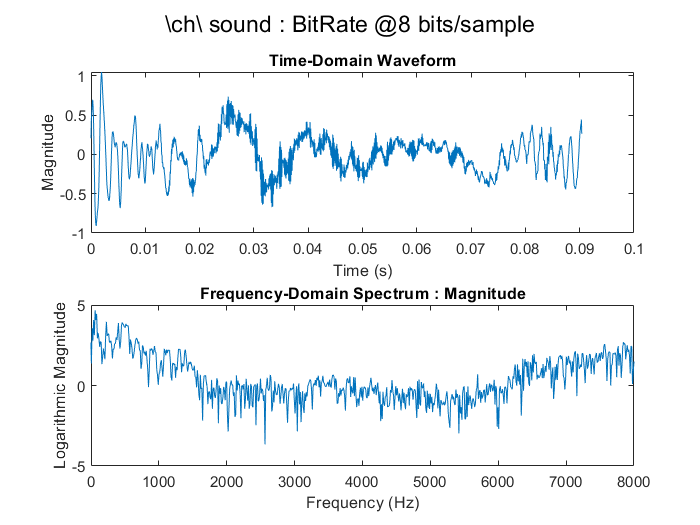

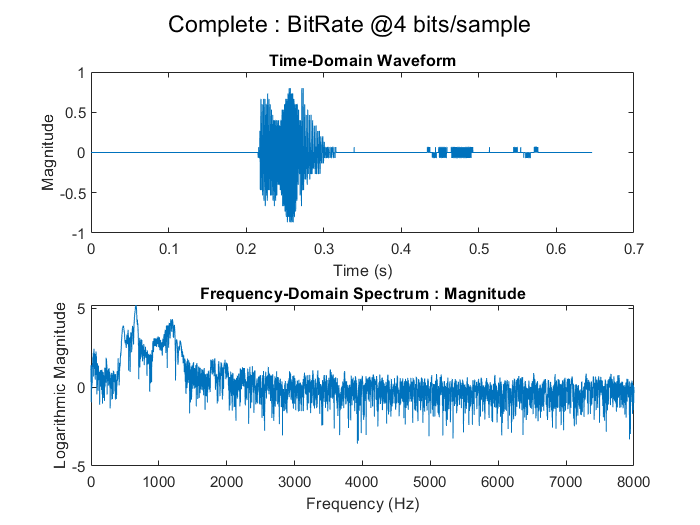

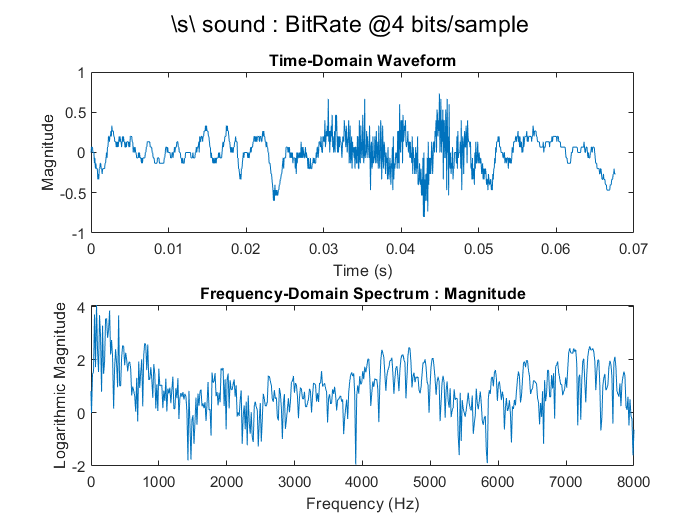

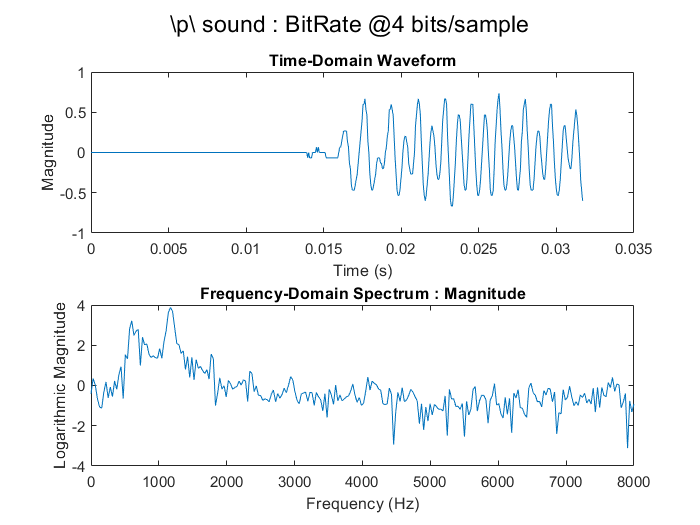


for i = 2:4
    bitResolution = bitResolutionList(i);
    quantLevel = quantLevels(i);
    Fs_Val = 16000;
    
    for j = 1:5
        
        soundArray = soundArrays{j};
        soundArray = round(soundArray.*quantLevel)./quantLevel;
        arrLen = length(soundArray);
        timeVector = linspace(0, arrLen, arrLen)/Fs_Val;
        
        soundArrayFFT = fftshift(fft(soundArray));
        freqVector = linspace(-Fs_Val/2, Fs_Val/2, arrLen);
        
        figure();
        sgtitle(strcat(string(soundList{j}), ' : BitRate @', string(bitResolution), ' bits/sample'));
        subplot(2, 1, 1);
        plot(timeVector, soundArray);
        title('Time-Domain Waveform');
        xlabel('Time (s)');
        ylabel('Magnitude');
        
        subplot(2, 1, 2);
        plot(freqVector, log(abs(soundArrayFFT)));
        title('Frequency-Domain Spectrum : Magnitude');
        xlabel('Frequency (Hz)');
        ylabel('Logarithmic Magnitude');
        xlim([0, Fs_Val/2]);
        
    end
    
end

Observations : As we decrease the bit depth, the quality of the sound signal decreases and its becomes more sensitive to the noise therefore the sound becomes less relevant and unusable.